# ASSIGNMENT 2

Gianpaolo Mastroiacovo(ge28tud)

Antonio Di Giovanni()

Data(04/05/2021)

## Exercise 2.1)

#### *a)*

P = [0.2 0.15 0.1 0.05 0.35 0.15];
N = [1 3 4 5 9 10];

Prob = [0.20 0 0.15 0.10 0.05 0 0 0 0.35 0.15];
Distr_X = makedist('Multinomial','Probabilities',Prob);
y = cdf(Distr_X, N) %Used to create a cumulative distribution function

y =     0.2000    0.3500    0.4500    0.5000    0.8500    1.0000


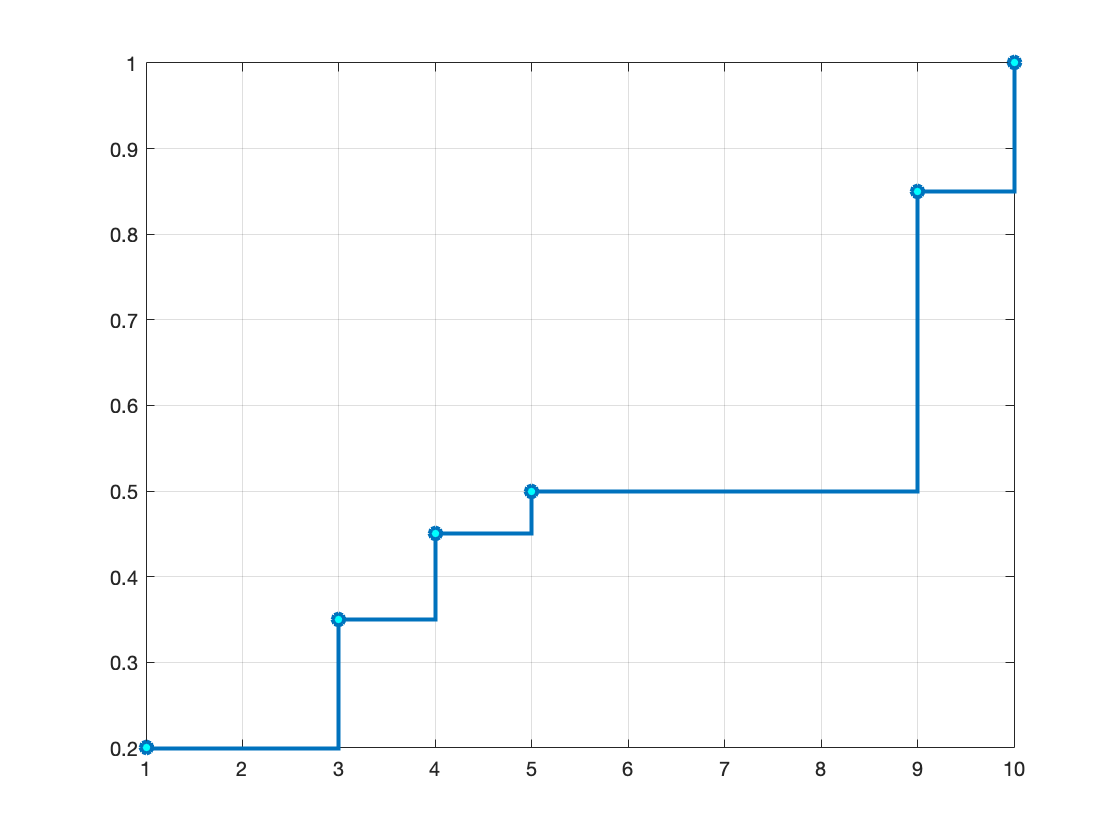

%p = plot(N,y,'ro');
stairs(N,y,'LineWidth',2,"Marker",'o',"MarkerFaceColor",'c')
hold on
grid
hold off

b)

meanX = sum(N.*P)

meanX = 5.9500

varX = sum((N-meanX).^2)/length(N) 

varX = 10.6025

## Exercise 2.2) 

#### *a)  *

*Solar* and *Wind* are two binary variables that model che choice to (1) or not to (0) built that kind of power plant.

$P_{\mathrm{solar}} \;\;\mathrm{and}\;P_{\mathrm{wind}} \;$are paramenters that represent each plant's profit in a scenario.

Following, the mathematical formulation of the deterministic case (= as if the scenario is known before)


$$\begin{array}{l}
\max_{\mathrm{Solar},\mathrm{Wind}} \;\;\;\;\mathrm{Solar}\cdot P_{\mathrm{solar}} +\mathrm{Wind}\cdot \;P_{\mathrm{wind}} \\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\;\;\mathrm{Solar}+\mathrm{Wind}=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Solar},\mathrm{Wind}\in \left\lbrace 0,1\right\rbrace 
\end{array}$$


#### *b)*

Solar = binvar(3,1);
Wind = binvar(3,1);

% Definition of Profits
Wind_Profit = [10; 50; 80];
Solar_Profit = [100; 60; 10];

% Enforcing only one plant to be chosen
Cons = Solar + Wind == 1;

% Solving the problem in every possible scenario
BestProfit = [];
for i = 1:3
obj = Solar(i)' * Solar_Profit(i) + Wind(i)' * Wind_Profit(i);

ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

res = optimize(Cons, -obj, ops);
BestProfit = [BestProfit; value(obj)];
end


value(Solar)

ans =      1
     1
     0


value(Wind)

ans =      0
     0
     1


value(BestProfit)

ans =    100
    60
    80


#### *c)*  

*Solar* and *Wind* are two binary variables that model the choice to (1) or not to (0) built that kind of power plant.

$P_{\textrm{solar}} \;\;\textrm{and}\;P_{\textrm{wind}} \;$are paramenters that represent each plant's profit in a scenario.


$$p_s \;\mathrm{stands}\;\mathrm{for}\;\mathrm{"probability}\;\mathrm{of}\;\mathrm{scenario}\;\mathrm{s"}$$



$$\begin{array}{l}
\max_{\mathrm{Solar},\mathrm{Wind}} \;\;\;\;\sum_{s=1}^3 p_s *\left(\mathrm{Solar}*{P^{\;\mathrm{solar}} }_s +\mathrm{Wind}*{P^{\;\mathrm{wind}} }_s \right)\\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\;\;\mathrm{Solar}+\mathrm{Wind}=1\;\;\;\;\;\;\;\;\;\;\mathrm{Solar},\mathrm{Wind}\in \left\lbrace 0,1\right\rbrace 
\end{array}$$


% Definition of Decision Variables
Solar = binvar(1);
Wind = binvar(1);

% Definition of Profits
Wind_Profit = [10; 50; 80];
Solar_Profit = [100; 60; 10];

% Enforcing only one plant to be chosen
Cons = Solar + Wind == 1;

obj = mean(Solar * Solar_Profit + Wind * Wind_Profit);

ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

result = optimize(Cons, -obj, ops);

value(Solar)

ans = 1

value(Wind)

ans = 0

value(obj)

ans = 56.6667

AverageScenarioSolution = mean(BestProfit)

AverageScenarioSolution = 80

In this case, the average of the optimal profits of each scenario is higher than the expected profit in the stochastic problem, since we are making decisions knowing the exact value of the profits in advance (and therefore always making the most profitable choice).

## Exercise 2.3)

#### *a)*

The expected wealth is defined as the sum of the capitals invested in each asset multiplied by its corresponding expected return $1+E\left(R_i \right)$.


$$E\left(W_t \right)=\sum_{i=1}^n x_i \cdot \left(1+E\left(R_i \right)\right)$$
  


$$\begin{array}{l}
\max_{x_1 ,\ldotp \ldotp \ldotp ,x_n } \;\sum_{i=1}^n x_i \cdot \left(1+E\left(R_i \right)\right)\\
s\ldotp t\\
\;\;\;\;\;\;\;\;\sum_{i=1}^n x_i \le {\;W}_0 \;\;\;\;\;\;x\in \Re \;
\end{array}$$


#### *b)*


$$\begin{array}{l}
\mu_i =1+E\left(R_i \right)\;\;\;\;i=1,2,\ldotp \ldotp \ldotp ,n\\
\mu_{\max } =\max_i \;\mu_i \;\;
\end{array}$$


The maximization function's domain is $0\le x\le W_0$, and its slopes are $u_i$. This means that it reaches its maximum exactly when investing the whole capital $W_0$ in the asset having the highest expected return ($\left.\mu_{\max } \right)$.


$$\max_x \;E\left(W_t \right)=W_0 \cdot \mu {\;}_{\max }$$


#### *c)*


$$\begin{array}{l}
\max_{x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n } \;\;\sum_{i=1}^n x_i \cdot \mu_i \\
s\ldotp t\\
\;\;\;\;\;\;\;\;\sum_{i=1}^n x_i \le W_0 \\
\;\;\;\;\;\;\;\;\;x^T \Sigma x\le v\;\;\;\;\;\;\;v\in \Re^+ 
\end{array}$$


#### *d)*

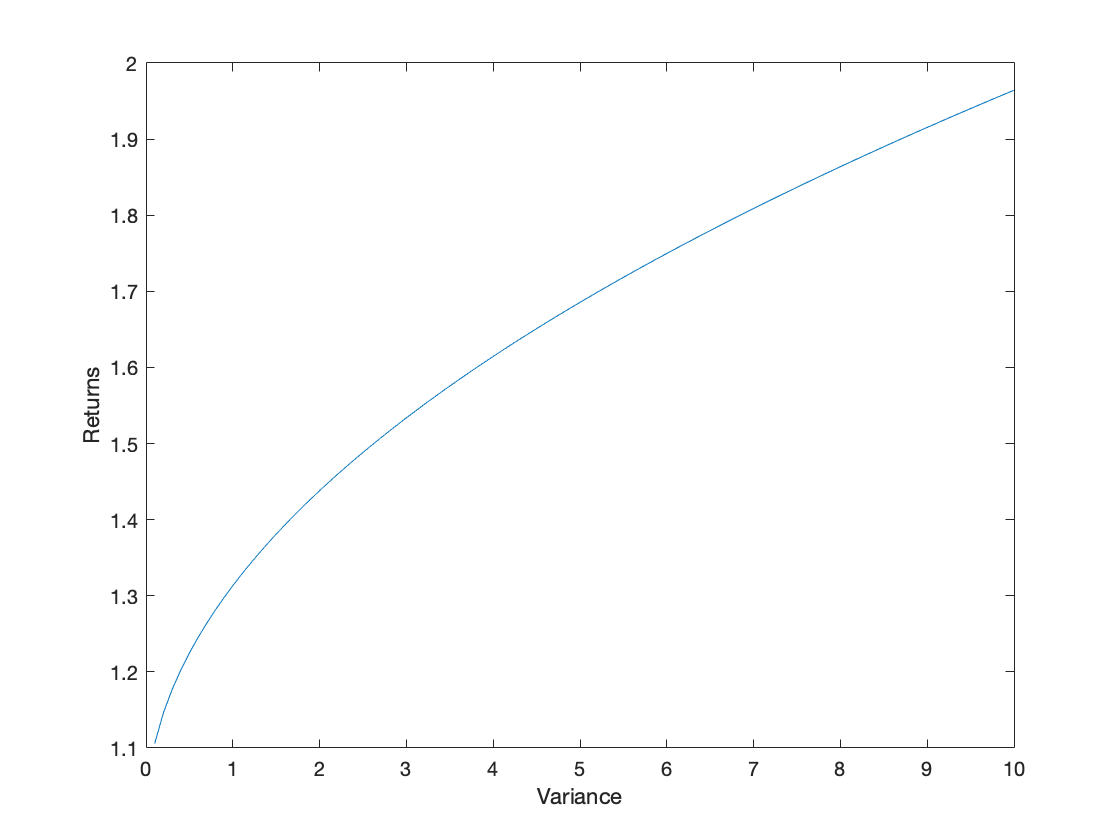

Cov = [0.017, 0.003, 0.001; 0.003, 0.006, 0.004; 0.001, 0.004, 0.063];
W_0 = 1;
mu = [1.026; 1.008; 1.074];
v = [0.1:0.1:10];
Results = [];

for i = 1:length(v)
x = sdpvar(3,1);

Cons = sum(x)<= W_0;
Cons = [Cons, (x'*Cov)*x <= v(i)];

obj = x'*mu;
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

res = optimize(Cons, -obj, ops);
Results = [Results, value(obj)];
end

figure
plot(v,Results);
xlabel('Variance');
ylabel('Returns');

## Exercise 2.4)


$$\begin{array}{l}
\min_{x_1 ,x_2 ,x_3 ,z} \;\;\;z\\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\begin{array}{l}
x_1 +\mathrm{x2}\ge \mathrm{x3}\\
x_1 ,\mathrm{x2},\mathrm{x3}\ge 0\\
3\mathrm{x1}\ge 2\\
z\ge 3x_1 -2\\
z\ge 4x_2 \\
\\
z\ge 2x_3 \\
z\ge x_1 +x_2 -x_3 
\end{array}
\end{array}$$


#### *b)*

% Decision Variables
z = sdpvar;
x1 = sdpvar;
x2 = sdpvar;
x3 = sdpvar;

% Objective Function
obj = z;

%Constraints
Cons = x1 + x2 >= x3;
Cons = [Cons, x1 >= 0];
Cons = [Cons, x2 >= 0];
Cons = [Cons, x3 >= 0];
Cons = [Cons, x1 >= 2/3];
Cons = [Cons, z >= 3*x1-2];
Cons = [Cons, z >= 4*x2];
Cons = [Cons, z >= 2*x3+1];
Cons = [Cons, z >= x1+x2+x3];

%Options
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

% Solve the problem
Res = optimize(Cons, obj, ops);      

value(obj)

ans = 1

value(x1)

ans = 0.6667

value(x2)

ans = 0

value(x3)

ans = 0

## Exercise 2.5)

#### *a)* 


$$\begin{array}{l}
\min_{x_1 ,x_2 ,x_3 ,y} \;\;\;{3x}_1 -{4x}_2 +x_3 \\
s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;\;\;\begin{array}{l}
x_1 +x_3 \ge x_2 \\
y\le 2\\
{y\ge \;x}_1 +x_2 \\
y\ge x_3 \;\\
{3x}_3 \le 5\\
x_1 \;,x_{2\;} ,x_3 \ge 0
\end{array}
\end{array}$$


#### *b)* 

% Decision Variables
y = sdpvar;
x1 = sdpvar;
x2 = sdpvar;
x3 = sdpvar;

% Objective Function
obj = 3 * x1 - 4 * x2 + x3;

%Constraints
Cons = x1 + x3 >= x2;
Cons = [Cons, x1 >= 0];
Cons = [Cons, x2 >= 0];
Cons = [Cons, x3 >= 0];
Cons = [Cons, 3 * x3 <= 5];
Cons = [Cons, y <= 2];
Cons = [Cons, y >= x1 + x2];
Cons = [Cons, y >= x3];

%Options
ops = sdpsettings('solver', 'gurobi', 'verbose', 0);

% Solve the problem
Res = optimize(Cons, obj, ops);       % The optimize function always minimizes

value(obj)

ans = -5.1667

value(x1)

ans = 0.1667

value(x2)

ans = 1.8333

value(x3)

ans = 1.6667

value(y)

ans = 2